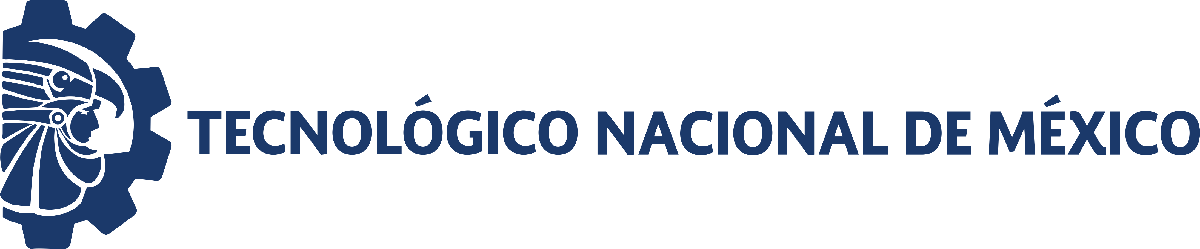                                 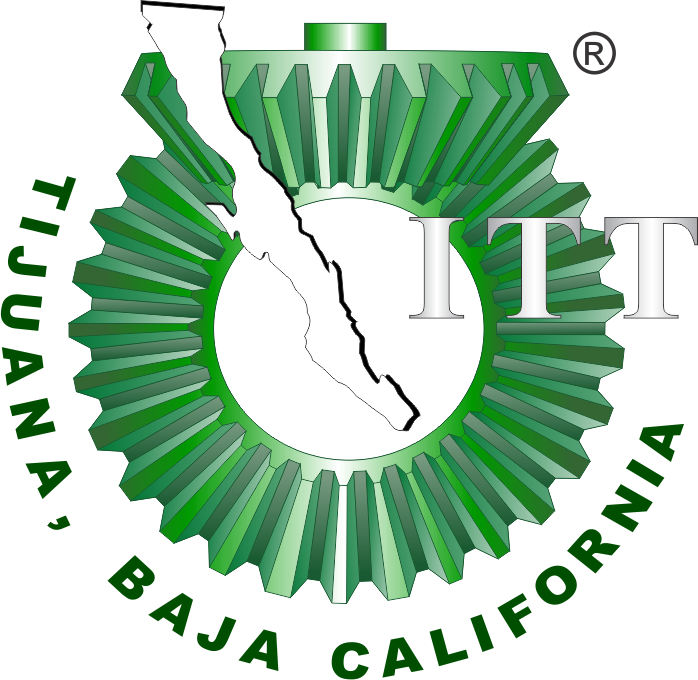

# Práctica 3: Sistema musculoesqueletico 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

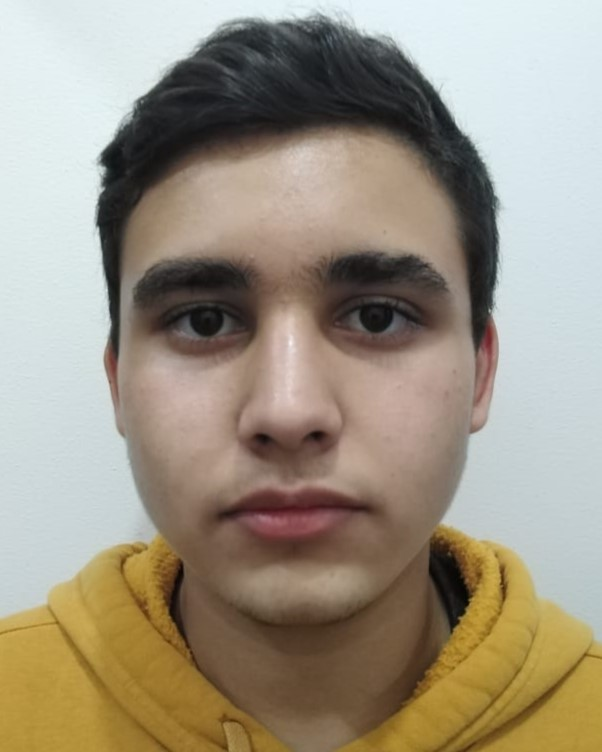

Nombre del alumno: **Rafael Herrera Aguilar**

Número de control: **22212258**

Correo institucional: **l22212258@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Practica_3_MSF';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';

## Gráfica Lazo Cerrado

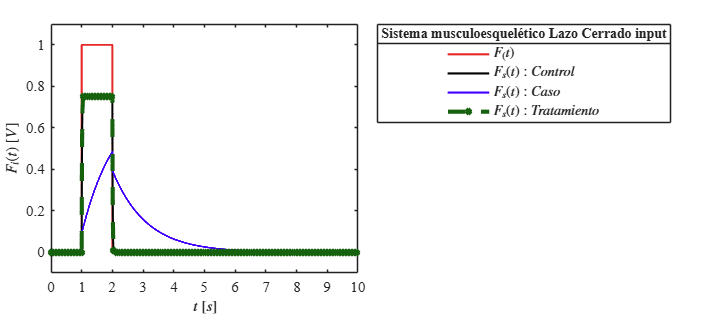

function plotsignals(t,Fs0,Fs1,Fs2,Fs3,Signal)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;

    mycolors = [230, 039, 039;
                0, 0, 0;
                067, 0, 255;
                022, 097, 014;
                250, 129, 047;
                145, 018, 188]/255;
    colororder(mycolors)

    p = plot(t,Fs0,'-',t,Fs1,'-',t,Fs2,'-',t,Fs3,'--x',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:100:length(t));
    set(p(4),'LineWidth',3); 
    L = legend('$F_(t)$','$F_{s}(t): Control$','$F_{s}(t): Caso$','$F_{s}(t): Tratamiento$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,[Signal,' input'],'FontSize',10)

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$F_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    xlim([0,10]); xticks(0:1:10)
    if Signal == "Sistema musculoesquelético Lazo Cerrado"
        ylim([-0.1,1.1]); yticks(-0.2:0.2:1.2)
    end

    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','Vector')
end

Signal = 'Sistema musculoesquelético Lazo Cerrado';
set_param('Practica_3_MSF/F(t)','Amplitude','1');
set_param('Practica_3_MSF/F(t)','Period','10');
set_param('Practica_3_MSF/F(t)','PulseWidth','10');
set_param('Practica_3_MSF/F(t)','PhaseDelay','1');
x1 = sim(file,parameters);
plotsignals(x1.t,x1.Fs0,x1.Fs1,x1.Fs2,x1.Fs3,Signal)

## Gráfica Lazo Abierto

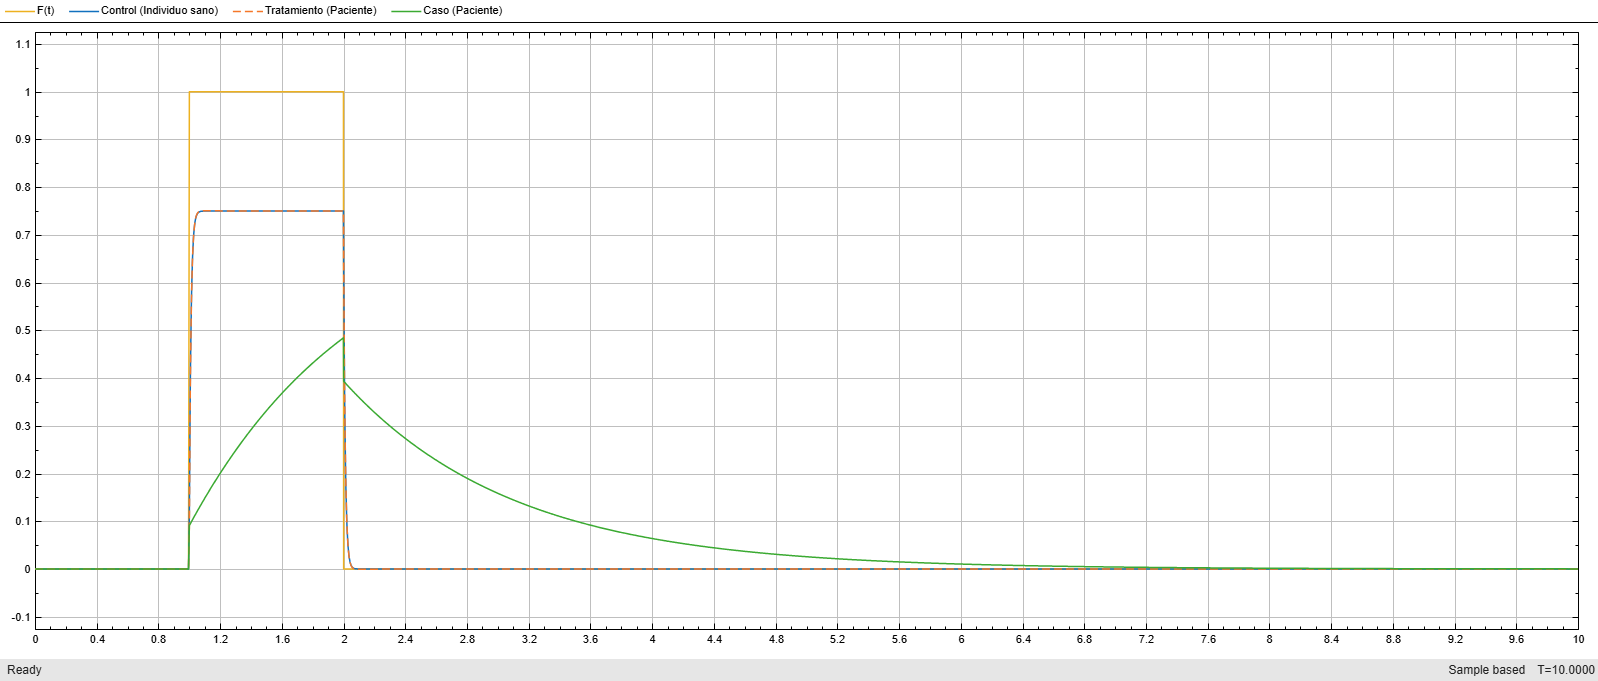

function plotsignals2(t,Fs0,Fs1,Fs2,Signal)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;

    mycolors = [230, 039, 039;
                0, 0, 0;
                067, 0, 255;
                022, 097, 014;
                250, 129, 047;
                145, 018, 188]/255;
    colororder(mycolors)

    p = plot(t,Fs0,'-',t,Fs1,'-',t,Fs2,'-',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(3),'LineWidth',3); 
    L = legend('$F_(t)$','$F_{s}(t): Control$','$F_{s}(t): Caso$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,[Signal,' input'],'FontSize',10)

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$F_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    xlim([0,10]); xticks(0:1:10)
    if Signal == "Sistema musculoesquelético Lazo Abierto"
        ylim([-0.1,1.1]); yticks(-0.2:0.2:1.2)
    end

    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','Vector')
end

Signal = 'Sistema musculoesquelético Lazo Abierto';
set_param('Practica_3_MSF/F(t)','Amplitude','1');
set_param('Practica_3_MSF/F(t)','Period','10');
set_param('Practica_3_MSF/F(t)','PulseWidth','10');
set_param('Practica_3_MSF/F(t)','PhaseDelay','1');
x2 = sim(file,parameters);

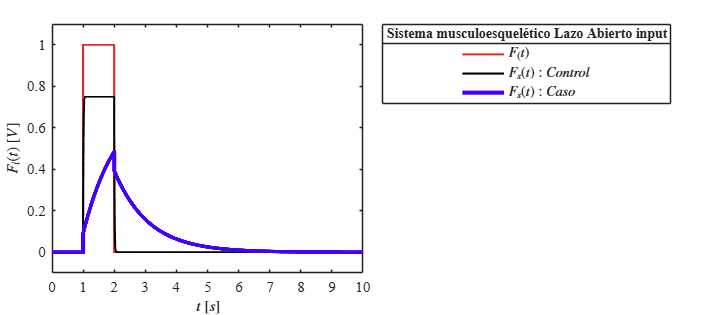

writematrix(x2.Fs0,'signal.xlsx')
plotsignals2(x2.t,x2.Fs0,x2.Fs1,x2.Fs2,Signal)